# Lab2

## Objectives

### Model identification

- Parameter estimation

- Calibration & validation

Empirical model for reservoir inflows

- Linear AR model

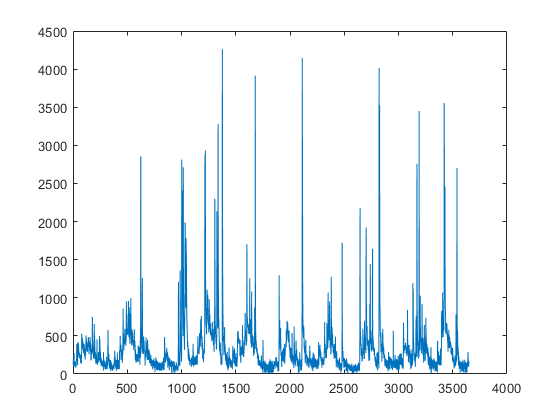

% Exercise 1 - Stationary statistics
data = load("data\Verbano_inflows_74_83_nb.txt");
% plot(data(:,2),data(:,1), '*')
plot(data)

N = length(data)

N = 3650

data_min = min(data)

data_min = 1.5000

data_max = max(data)

data_max = 4.2614e+03

data_range = range(data)

data_range = 4.2599e+03

data_mean = mean(data)

data_mean = 321.3367

data_var = var(data)

data_var = 1.2365e+05

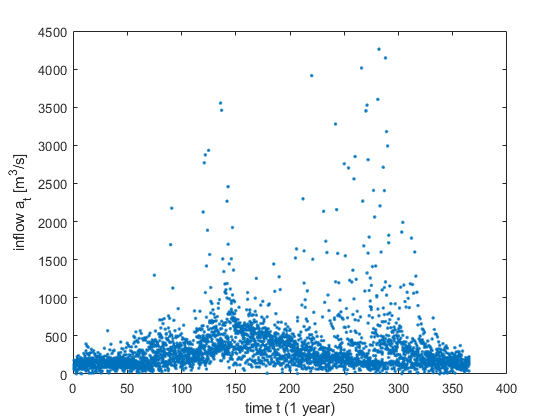

% Exercise 2 - Cyclostationary statistics

% Periodicity
T = 365;
tt = repmat([1:T]', N/T, 1);
figure;
plot(tt ,data ,'.' );
xlabel('time t (1 year)'); 
ylabel('inflow a_t [m^3/s]');

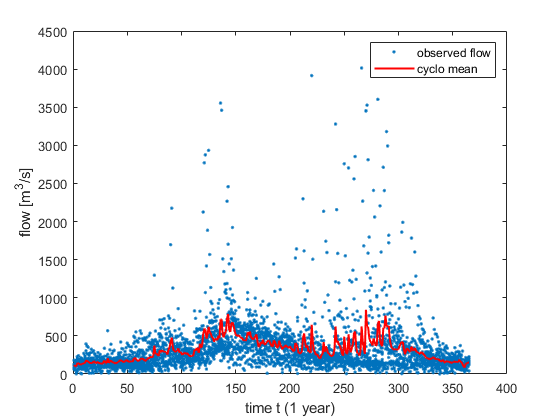

Q = reshape(data, T, 10);
% Cyclo-stationary mean
Cm = mean(Q,2); % Same as mean(Q')'
% Cyclo-stationary variance
Cv = var(Q')';
plot(tt, data, '.' );
hold on;
plot(Cm, 'r', 'LineWidth', 1.5); 
legend('observed flow', 'cyclo mean');
xlabel('time t (1 year)');
ylabel('flow [m^3/s]');


% for i=1 : size(two_years)/365
%     fprintf('Year %d \n',i);
%     start_day = (i-1)*365 + 1;
%     end_day = i*365;
%     m = mean(two_years(start_day:end_day))
%     v = var(two_years(start_day:end_day))
% end

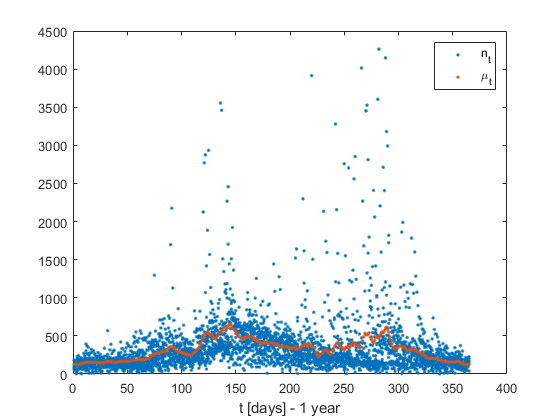

% Exercise 3 - Cyclostationary moving variance
T = 365;
f = 3;
[mi, m] = moving_average(data, T, f);
figure;
plot(tt, [data, m], '.');
xlabel('t [days] - 1 year');
legend('n_t', '\mu_t');

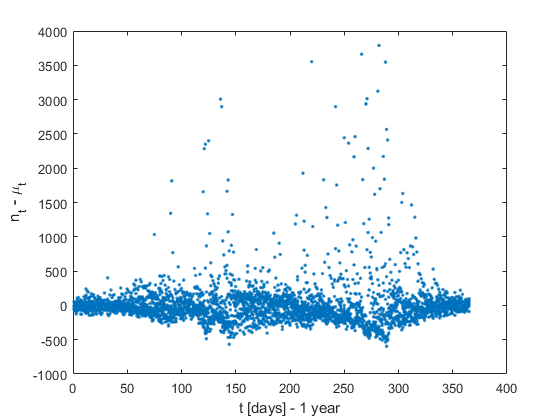

figure;
plot(tt, data - m, '.')
xlabel('t [days] - 1 year');
ylabel('n_t - \mu_t')

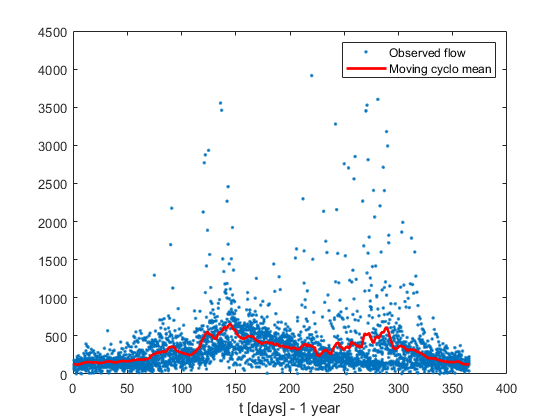

[ma_var2, s2] = moving_average((data - m).^2, T, f);
ma_var = ma_var2.^(1/2);
s = s2.^(1/2);

figure;
plot(tt, data, '.');
hold on;
plot([1 : T], mi, 'r', 'LineWidth',2);
legend('Observed flow', 'Moving cyclo mean');
xlabel('t [days] - 1 year');

% Exercise 4 - Param identification, linear model


% Homework - Approximate power law model


% Exercise 5 - AR(1) estimation